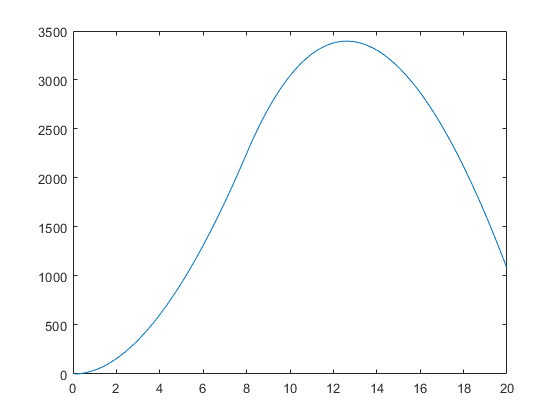

clc
clear

syms s t

tmin = 0.1;
tstep = 0.1;
tmax = 20;

k = 3;
m = 50;
force = 900;
f = force * (heaviside(t) - heaviside(t-8)) - m*9.8;
%f = -m*9.8;

% laplace domain

tran_s = 1 / (s*m + k);
f_s = laplace(f, s);
v_s = f_s * tran_s;
v = ilaplace(v_s);
h = int(v, t);

%run data only until end
%tmax = solve(v, 0);
%tmax = double(tmax(2))

test = subs(h, t, 0);

%solution

v = double(subs(v, t, tmin:tstep:tmax));
h = cumtrapz(v);
f = double(subs(f, t, tmin:tstep:tmax));
t = tmin:tstep:tmax;

% we have velocity integrate for height



plot(t, h)